# Defining A Source Using An Array Transducer Example

kWaveArray permite definir elementos de un transductor en coordenadas físicas independientes de la discretización de la malla. Posteriormente, la geometría y las señales de los elementos se distribuyen sobre kgrid, reduciendo los errores de staircasing asociados a máscaras binarias convencionales.

In this example, three arc-shaped elements are added to the array using the `addArcElement` method. 

% create empty array
karray = kWaveArray;

% define arc properties
radius    = 50e-3;              % [m]
diameter  = 30e-3;              % [m]
focus_pos = [-20e-3, 0];        % [m]

% add arc shaped element
elem_pos  = [10e-3, -40e-3];    % [m]
karray.addArcElement(elem_pos, radius, diameter, focus_pos);

% add arc shaped element
elem_pos  = [20e-3, 0];         % [m]
karray.addArcElement(elem_pos, radius, diameter, focus_pos);

% add arc shaped element
elem_pos  = [10e-3, 40e-3];     % [m]
karray.addArcElement(elem_pos, radius, diameter, focus_pos);

The array defines the positions of the elements relative to the k-Wave Cartesian coordinate system, which defines the origin centered on the grid. After defining the element positions, it is possible to move the entire array to a different position in space by defining a transformation. The position can be defined using `setArrayPosition` which takes the translation and rotation of the array, or alternatively using `setAffineTransform` which directly sets the array transform.

% move the array down 10 mm, and rotate by 10 degrees (this moves all the
% elements together)
karray.setArrayPosition([10e-3, 0], 10);

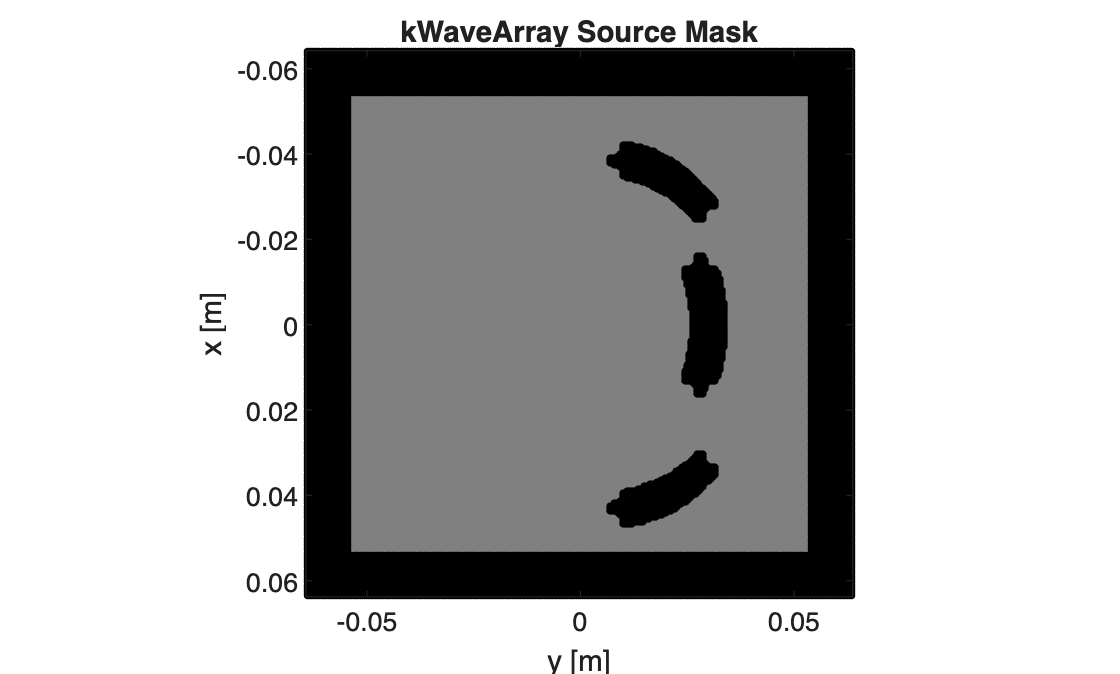

clear all;
close all;
clc;

Nx = 256;
Ny = 256;

dx = 0.5e-3;   % [m]
dy = 0.5e-3;   % [m]

kgrid = kWaveGrid(Nx, dx, Ny, dy);

karray = kWaveArray;


% addArcElement:
% posición del centro del arco
% radio de curvatura
% diámetro de apertura
% punto hacia donde apunta el arco

focus_pos = [0, 0];

% Arco izquierdo
karray.addArcElement( ...
    [-0.035, 0.020], ...    % posición [x,y] en m
    0.030, ...              % radio de curvatura [m]
    0.020, ...              % apertura [m]
    focus_pos);

% Arco central
karray.addArcElement( ...
    [0.000, 0.030], ...
    0.040, ...
    0.025, ...
    focus_pos);

% Arco derecho
karray.addArcElement( ...
    [0.040, 0.020], ...
    0.030, ...
    0.020, ...
    focus_pos);

% Proyecta los elementos físicos del kWaveArray sobre kgrid.
source.p_mask = ...
    karray.getArrayBinaryMask(kgrid);


PML_SIZE = 20;

pml_mask = false(Nx, Ny);

pml_mask(1:PML_SIZE,:) = true;
pml_mask(end-PML_SIZE+1:end,:) = true;

pml_mask(:,1:PML_SIZE) = true;
pml_mask(:,end-PML_SIZE+1:end) = true;



figure;

% Fondo blanco
imagesc( ...
    kgrid.y_vec, ...
    kgrid.x_vec, ...
    zeros(Nx,Ny));

hold on;
colormap(gray)
axis image;

xlabel('y [m]');
ylabel('x [m]');

title('kWaveArray Source Mask');


%% =========================================================

% 7. MOSTRAR PML EN NEGRO
% ==========================================================

[x_pml, y_pml] = find(pml_mask);

scatter( ...
    kgrid.y_vec(y_pml), ...
    kgrid.x_vec(x_pml), ...
    8, ...
    'k', ...
    'filled');


% Esta máscara es ligeramente más gruesa que la geometría física
% por el BLI usado por kWaveArray.

[x_mask, y_mask] = find(source.p_mask);

scatter( ...
    kgrid.y_vec(y_mask), ...
    kgrid.x_vec(x_mask), ...
    10, ...
    'k', ...
    'filled');

`getArrayBinaryMask(kgrid)` proyecta la geometría física definida por `kWaveArray` sobre la malla computacional y genera la máscara binaria usada por k-Wave como fuente. Debido al uso de BLI, la máscara puede extenderse alrededor de la geometría física del elemento.

Generamos las senales que seran emitidas por cada transductor

% Medio
medium.sound_speed = 1500;
medium.density = 1000;

% Tiempo
t_end = 80e-6;
kgrid.t_array = makeTime(kgrid, medium.sound_speed, [], t_end);

% Señales por elemento

Computing distributed source signal...
  calculating binary mask...                  completed in 0.009988s
  approximate size of source matrix:          5.2 MB (double precision)
  calculating element 1 grid weights...       completed in 0.017939s
  calculating element 1 distributed source... completed in 0.000807s
  calculating element 2 grid weights...       completed in 0.007651s
  calculating element 2 distributed source... completed in 0.003207s
  calculating element 3 grid weights...       completed in 0.00857s
  calculating element 3 distributed source... completed in 0.001781s
  total computation time 0.074319s


f1 = 100e3;
f2 = 200e3;
f3 = 500e3;

sig1 = toneBurst(1/kgrid.dt, f1, 3);
sig2 = toneBurst(1/kgrid.dt, f2, 5);
sig3 = toneBurst(1/kgrid.dt, f3, 5);

% Combinar señales
max_length = max([length(sig1), length(sig2), length(sig3)]);

source_signal = zeros(3, max_length);

source_signal(1,1:length(sig1)) = sig1;
source_signal(2,1:length(sig2)) = sig2;

Running k-Wave simulation...
  start time: 31-Aug-2026 15:42:41
  reference sound speed: 1500m/s
  dt: 100ns, t_end: 80.1us, time steps: 802
  input grid size: 256 by 256 grid points (128 by 128mm)
  maximum supported frequency: 1.5MHz
  expanding computational grid...
  computational grid size: 296 by 296 grid points
           Use dimension sizes with lower prime factors to improve speed
  casting variables to single type...
  precomputation completed in 0.35393s
  starting time loop...
  estimated simulation time 9.6268s...
  simulation completed in 7.5125s
  total computation time 7.8941s


source_signal(3,1:length(sig3)) = sig3;

% Distribuir señales sobre la máscara
source.p = karray.getDistributedSourceSignal( ...
    kgrid, ...
    source_signal);
% Opciones de simulación
input_args = { ...
    'PMLInside', false, ...
    'PMLSize', 20, ...
    'PlotPML', true, ...
    'PlotSim', true, ...
    'DataCast', 'single'};

% Ejecutar simulación
sensor_data = kspaceFirstOrder2D( ...
    kgrid, ...
    medium, ...
    source, ...
    [], ...
    input_args{:});

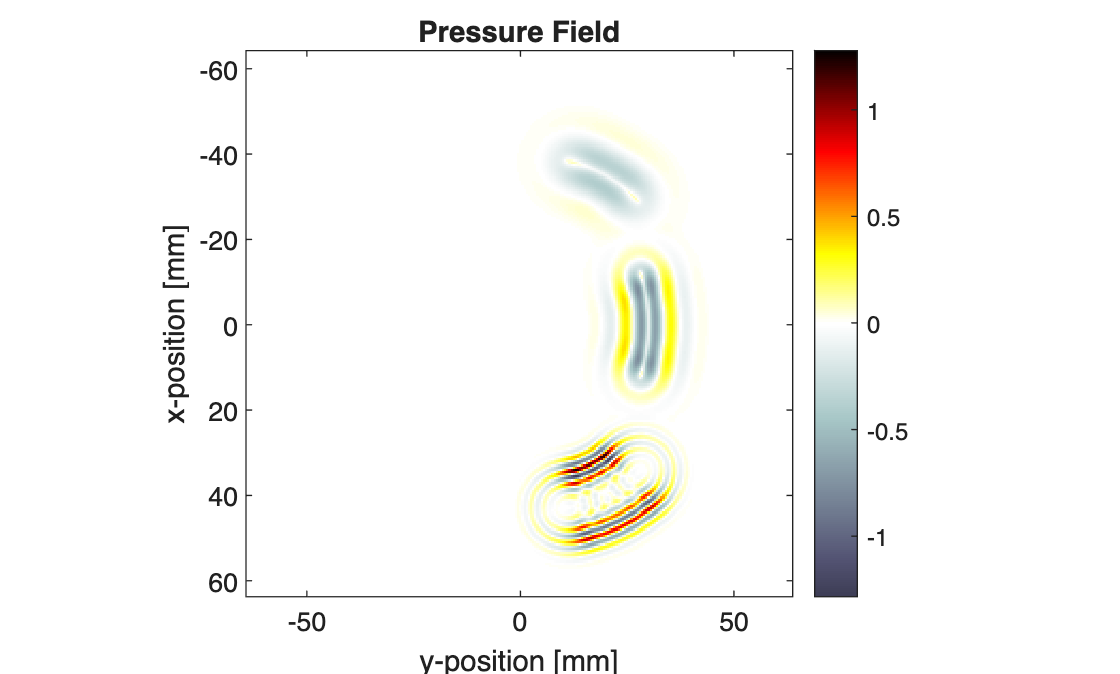

% Plotear campo de presión en un instante

time_index = 100;

p_snapshot = reshape( ...

    sensor_data.p(:, time_index), ...
    Nx, Ny);

figure;

imagesc( ...
    kgrid.y_vec * 1e3, ...
    kgrid.x_vec * 1e3, ...
    p_snapshot);

axis image;

colormap(getColorMap);

xlabel('y-position [mm]');
ylabel('x-position [mm]');

title('Pressure Field');

colorbar;

En la imagen se observa cómo cada uno de los tres elementos curvos genera un campo acústico diferente. Como cada elemento fue excitado con una frecuencia distinta, también aparecen diferentes longitudes de onda:

- 100 kHz → ondas más separadas. 

- 200 kHz → separación intermedia. 

- 500 kHz → ondas más juntas.

Se registró la presión acústica en todo el dominio y se seleccionó un instante temporal para visualizar la propagación generada por los tres elementos del `kWaveArray.`

# Defining A Sensor Using An Array Transducer Example

Este ejemplo es el equivalente del anterior, pero ahora `kWaveArray` se usa como **receptor** en vez de fuente. 

The syntax for creating a sensor is thus identical to the previous example. Here, an array is created with 20 arc-shaped elements placed around the outside of a circle, where the elements all point to the center.

Se crean 20 elementos curvos distribuidos alrededor de un círculo y orientados hacia el centro del dominio.

% Crear array
karray = kWaveArray;

% Geometría de los 20 elementos
radius_of_curv = 100e-3;
diameter       = 8e-3;
ring_radius    = 50e-3;
num_elements   = 20;

% Todos apuntan al centro
focus_pos = [0, 0];


% generate the centre position for each element in Cartesian space using
% makeCartCircle (these positions could also be defined manually, etc)
elem_pos = makeCartCircle(ring_radius, num_elements, [0, 0]);

% Añadir los elementos al array
% add elements to the array
for ind = 1:num_elements
    karray.addArcElement(elem_pos(:, ind), radius_of_curv, diameter, focus_pos);
end

Luego generas la máscara de sensor:

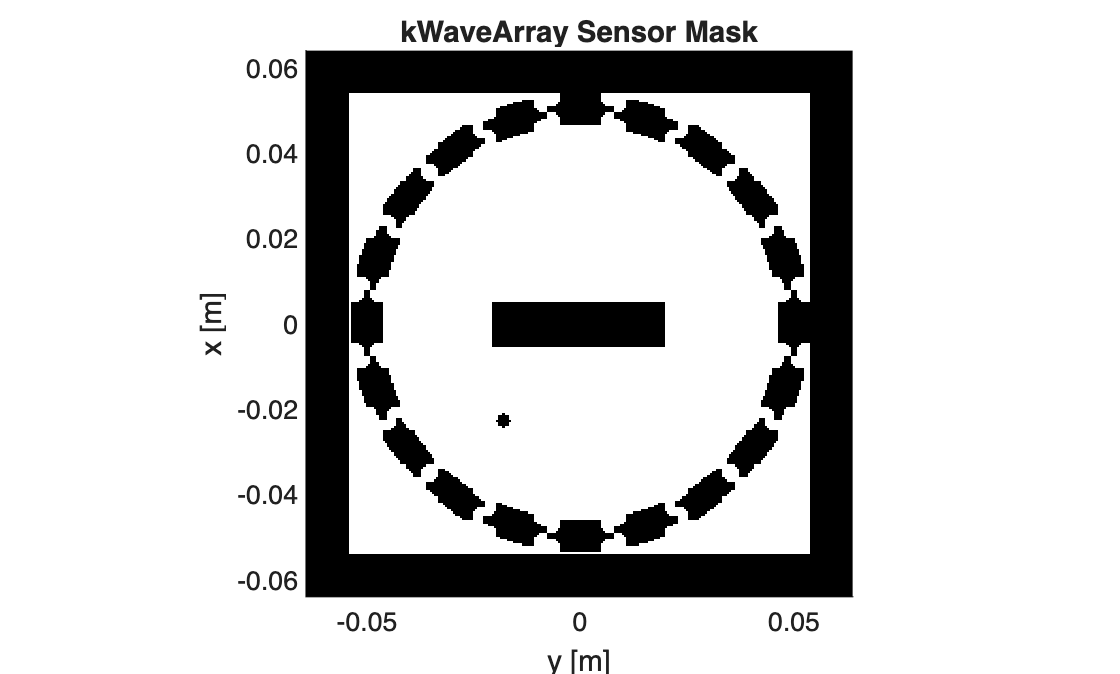

%% GRID
Nx = 256;
Ny = 256;

dx = 0.5e-3;
dy = 0.5e-3;

kgrid = kWaveGrid(Nx, dx, Ny, dy);

%% MEDIO
medium.sound_speed = 1500;
medium.density = 1000;

t_end = 120e-6;
kgrid.t_array = makeTime(kgrid, medium.sound_speed, [], t_end);

% SOURCE.P0
source.p0 = zeros(Nx, Ny);

source.p0( ...
    round(Nx/2)-10:round(Nx/2)+10, ...
    round(Ny/2)-40:round(Ny/2)+40) = 1;

circle = makeDisc( ...
    Nx, Ny, ...
    round(Nx/2)-45, ...
    round(Ny/2)-35, ...
    3);

source.p0(circle == 1) = 1;


% Imagen blanca
plot_mask = ones(Nx, Ny);

% Sensor BLI en negro
plot_mask(sensor.mask == 1) = 0;

% Source p0 en negro
plot_mask(source.p0 ~= 0) = 0;

% PML en negro
plot_mask(1:PML_SIZE, :) = 0;
plot_mask(end-PML_SIZE+1:end, :) = 0;
plot_mask(:, 1:PML_SIZE) = 0;
plot_mask(:, end-PML_SIZE+1:end) = 0;

% Plot
figure;
hold on;

imagesc( ...
    kgrid.y_vec, ...

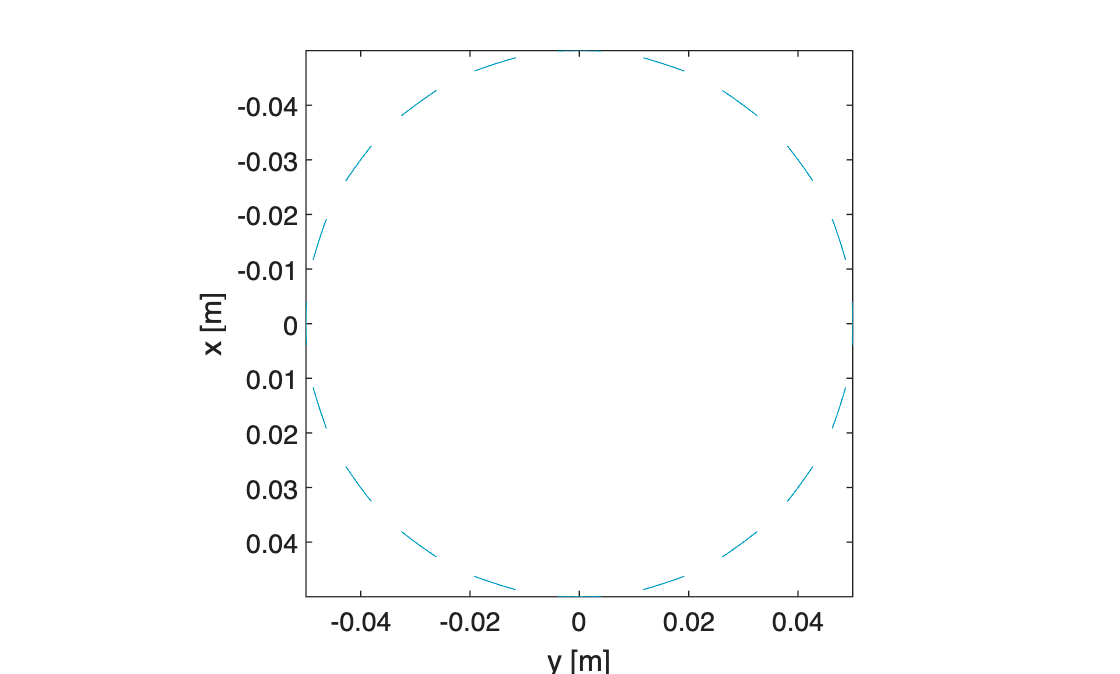

    kgrid.x_vec, ...

    plot_mask);

axis image;
colormap(gray);

xlabel('y [m]');
ylabel('x [m]');
title('kWaveArray Sensor Mask');

% Geometría física de los elementos
hold off
karray.plotArray;

Luego ejectuamos simulacion:

clear all;
close all;
clc;

%% GRID

Nx = 256;
Ny = 256;

dx = 0.5e-3;
dy = 0.5e-3;

kgrid = kWaveGrid(Nx, dx, Ny, dy);

%% MEDIUM

medium.sound_speed = 1500;
medium.density = 1000;

t_end = 120e-6;

kgrid.t_array = makeTime( ...
    kgrid, ...
    medium.sound_speed, ...
    [], ...
    t_end);

%% SOURCE.P0
% Fuente inicial independiente del kWaveArray

source.p0 = zeros(Nx, Ny);

% Rectángulo
source.p0( ...
    round(Nx/2)-10 : round(Nx/2)+10, ...
    round(Ny/2)-40 : round(Ny/2)+40) = 1;

% Círculo pequeño
circle = makeDisc( ...
    Nx, ...
    Ny, ...
    round(Nx/2)-45, ...
    round(Ny/2)-35, ...
    3);

source.p0(circle == 1) = 1;

%% CREAR kWaveArray

karray = kWaveArray;

radius_of_curv = 100e-3;
diameter       = 8e-3;
ring_radius    = 50e-3;
num_elements   = 20;

focus_pos = [0, 0];

% Centros de los 20 elementos
elem_pos = makeCartCircle( ...
    ring_radius, ...
    num_elements, ...
    [0, 0]);

% Añadir arcos
for ind = 1:num_elements

    karray.addArcElement( ...
        elem_pos(:, ind), ...
        radius_of_curv, ...
        diameter, ...
        focus_pos);

end

%% SENSOR MASK
% kWaveArray usado como receptor

sensor.mask = ...
    karray.getArrayBinaryMask(kgrid);

%% VISUALIZAR GEOMETRÍA

PML_SIZE = 20;

plot_mask = ones(Nx, Ny);

% Sensor mask
plot_mask(sensor.mask == 1) = 0;

% Source p0
plot_mask(source.p0 ~= 0) = 0;

% PML
plot_mask(1:PML_SIZE,:) = 0;
plot_mask(end-PML_SIZE+1:end,:) = 0;
plot_mask(:,1:PML_SIZE) = 0;
plot_mask(:,end-PML_SIZE+1:end) = 0;

%% SIMULACIÓN, si no se quita suavizado no cargara correctamente
input_args = { ...
    'PMLInside', true, ...
    'PMLSize', 20, ...
    'PlotPML', true, ...

Running k-Wave simulation...
  start time: 31-Aug-2026 16:03:04
  reference sound speed: 1500m/s
  dt: 100ns, t_end: 120us, time steps: 1201
  input grid size: 256 by 256 grid points (128 by 128mm)
  maximum supported frequency: 1.5MHz
  casting variables to single type...
  precomputation completed in 0.49962s
  starting time loop...
  estimated simulation time 8.3471s...
  simulation completed in 7.4151s
  recasting variables to double...
  total computation time 7.9491s


    'Smooth', false, ...
    'DataCast', 'single', ...
    'DataRecast', true};

sensor_data = kspaceFirstOrder2D( ...
    kgrid, ...
    medium, ...
    source, ...
    sensor, ...
    input_args{:});


sensor_data:


%% COMBINAR SENSOR DATA

        6724        1201



% Grid points -> una señal por arco físico


combined_sensor_data:


combined_sensor_data = ...

          20        1201



    karray.combineSensorData( ...
        kgrid, ...
        sensor_data);

%% COMPROBAR DIMENSIONES
disp('sensor_data:');
disp(size(sensor_data));

disp('combined_sensor_data:');
disp(size(combined_sensor_data));

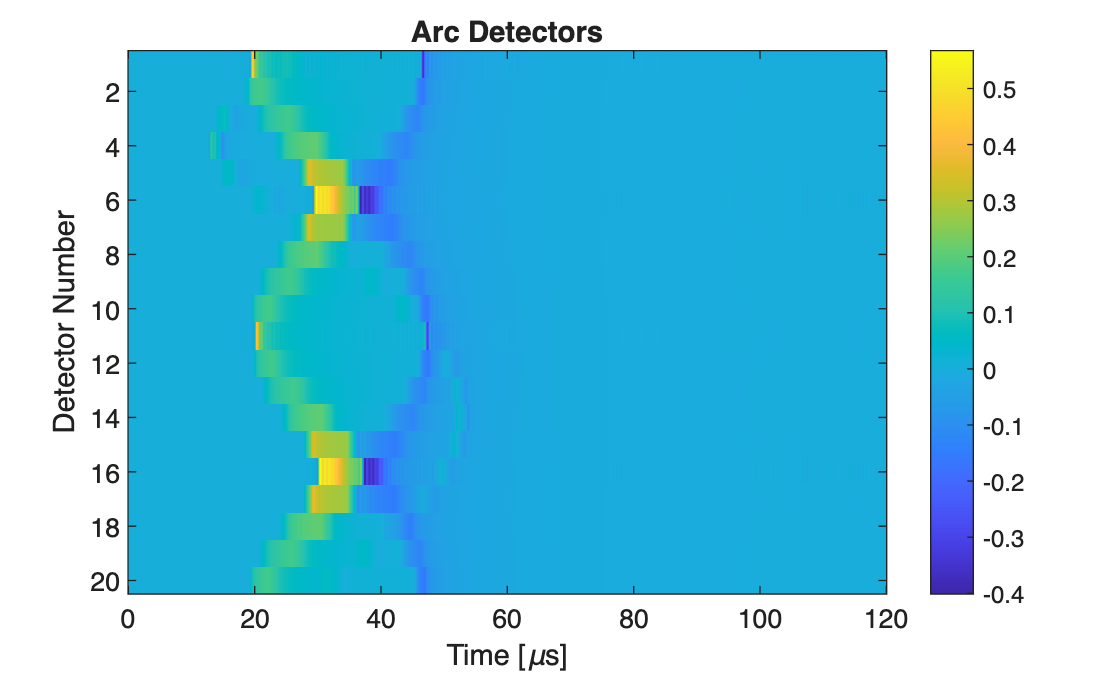

%% ARC DETECTORS
figure;

imagesc( ...
    kgrid.t_array * 1e6, ...
    1:num_elements, ...
    combined_sensor_data);

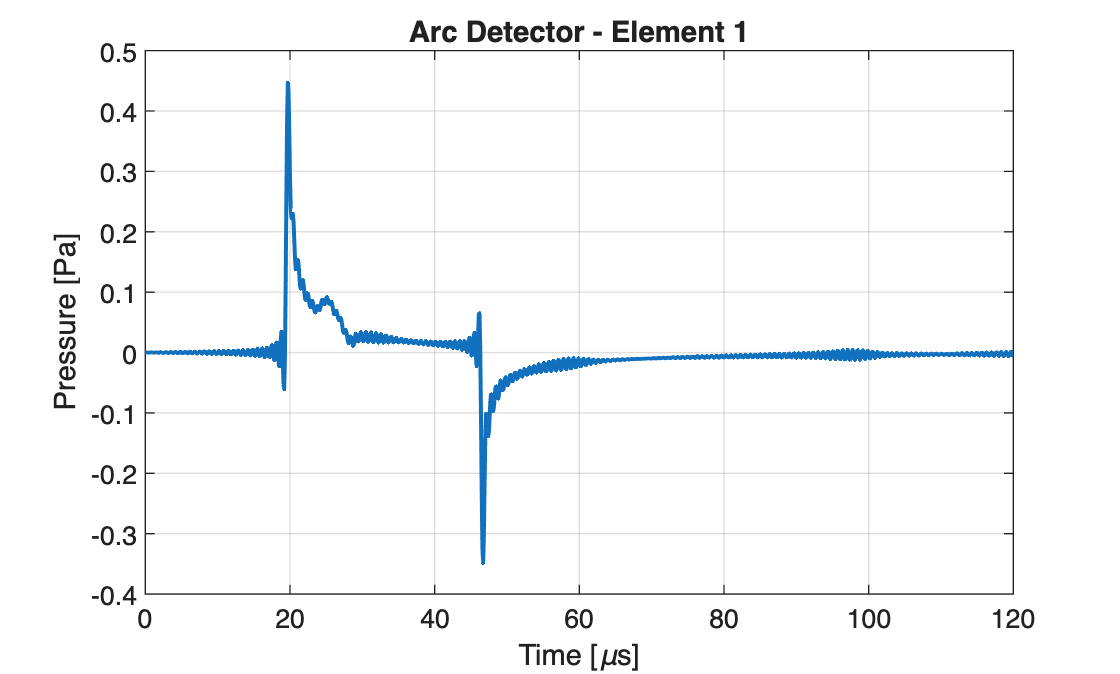


axis tight;

xlabel('Time [\mus]');
ylabel('Detector Number');

title('Arc Detectors');

colorbar;
%% PRIMER ARC DETECTOR
figure;
plot( ...
    kgrid.t_array * 1e6, ...

    combined_sensor_data(1,:), ...
    'LineWidth', 1.5);

xlabel('Time [\mus]');
ylabel('Pressure [Pa]');

title('Arc Detector - Element 1');

grid on;

El resultado demuestra que los elementos definidos mediante `kWaveArray` están funcionando como **receptores acústicos**. El detector no genera la onda; únicamente registra las perturbaciones de presión que llegan desde las fuentes iniciales.

La existencia de eventos en distintos tiempos se debe a que las dos regiones de `source.p0` se encuentran a diferentes distancias respecto al elemento analizado. Por tanto, las ondas necesitan diferentes tiempos de propagación para alcanzar el sensor.

Además, la señal no aparece como un impulso ideal, sino como una forma temporal más compleja. Esto ocurre porque cada elemento curvo ocupa una región espacial y la señal final es obtenida combinando la presión registrada en múltiples puntos de la malla asociados con ese elemento.

# Modelling A Linear Array Transducer Example

Se usara Karray para modelar un transductor lineal con 15 elementos rectangulares

% Se crea un kWaveArray vacío:
karray = kWaveArray('BLITolerance', 0.05, 'UpsamplingRate', 10);

% Luego se añaden 15 elementos rectangulares con addRectElement. 
% Los elementos se colocan uno al lado del otro usando un element_pitch fijo, formando un transductor lineal.
for ind = 1:element_num
    
    % set element y position
    x_pos = 0 - (element_num * element_pitch / 2 - element_pitch / 2) + (ind - 1) * element_pitch;
    
    % add element (set rotation angle to match the global rotation angle)
    karray.addRectElement([x_pos, 0, kgrid.z_vec(1)], element_width, element_length, rotation);
    
end

% permite trasladar y rotar todo el transductor.
karray.setArrayPosition(translation, rotation)

%La ventaja frente a kWaveTransducer es que kWaveArray permite geometrías y posiciones mucho más libres, 
% pero no calcula automáticamente delays, beamforming, scan lines ni elevation focusing.

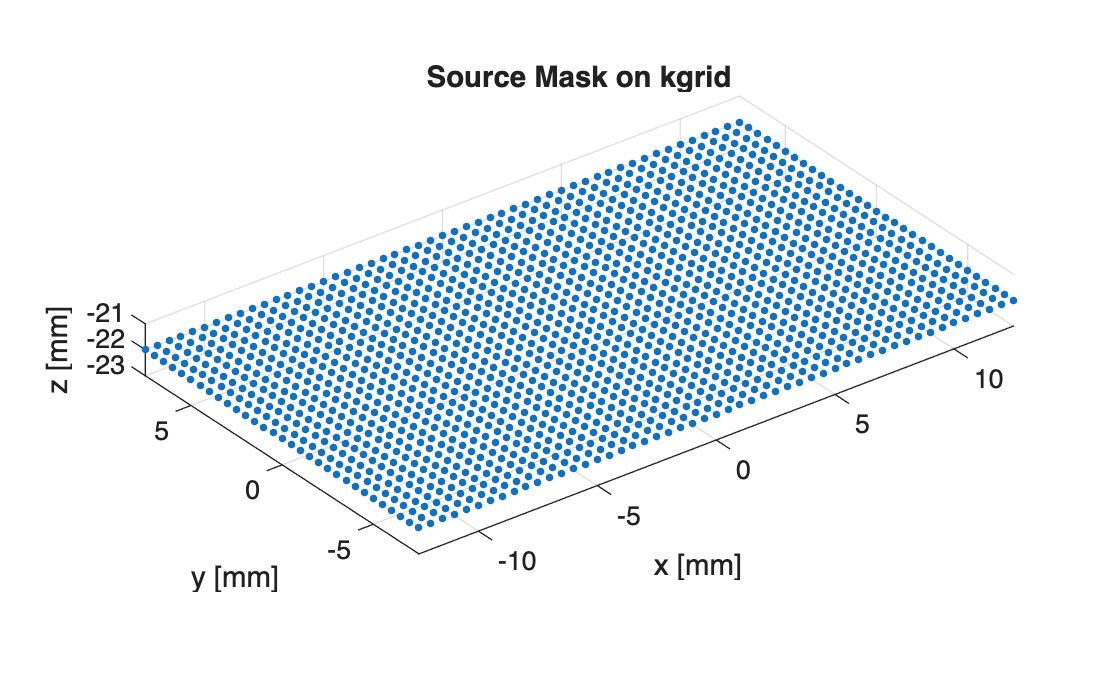

clear all;
close all;
clc;

%% GRID

Nx = 128;
Ny = 128;
Nz = 128;

dx = 0.5e-3;
dy = 0.5e-3;
dz = 0.5e-3;

kgrid = kWaveGrid( ...
    Nx, dx, ...
    Ny, dy, ...
    Nz, dz);

%% MEDIUM

c0 = 1500;
rho0 = 1000;

medium.sound_speed = c0;
medium.density = rho0;

%% TRANSDUCER PARAMETERS

element_num = 15;

element_width  = 1.0e-3;
element_length = 8e-3;
element_pitch  = 1.2e-3;

translation = [0, 0, 10e-3];

rotation = [0, 0, 0];

%% CREATE kWaveArray

karray = kWaveArray( ...
    'BLITolerance', 0.05, ...
    'UpsamplingRate', 10);

%% ADD RECTANGULAR ELEMENTS

for ind = 1:element_num

    x_pos = ...
        -(element_num * element_pitch / 2 ...
        - element_pitch / 2) ...
        + (ind - 1) * element_pitch;

    karray.addRectElement( ...
        [x_pos, 0, kgrid.z_vec(1)], ...
        element_width, ...
        element_length, ...
        rotation);

end

%% MOVE ARRAY

karray.setArrayPosition( ...
    translation, ...
    rotation);

%% SHOW TRANSDUCER GEOMETRY

%% CREATE BINARY MASK

source.p_mask = ...
    karray.getArrayBinaryMask(kgrid);

%mostrar array
[x_ind, y_ind, z_ind] = ind2sub( ...

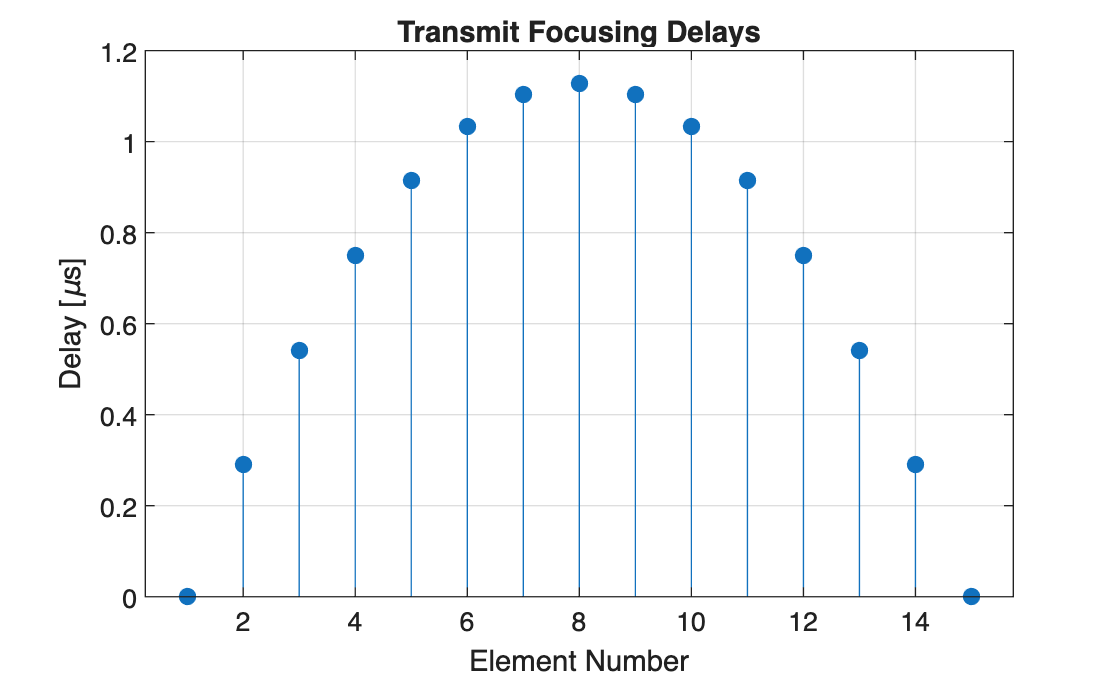

    size(source.p_mask), ...
    find(source.p_mask));

figure;

scatter3( ...
    kgrid.x_vec(x_ind) * 1e3, ...
    kgrid.y_vec(y_ind) * 1e3, ...
    kgrid.z_vec(z_ind) * 1e3, ...
    8, ...
    'filled');

xlabel('x [mm]');
ylabel('y [mm]');
zlabel('z [mm]');

title('Source Mask on kgrid');

axis equal;
grid on;
view(3);
% SOURCE PARAMETERS
source_f0 = 500e3;
source_cycles = 5;
source_amp = 1e6;

source_focus = 20e-3;

%% TIME ARRAY

ppw = c0 / source_f0 / dx;

CFL = 0.3;

t_end = 60e-6;

kgrid.t_array = makeTime( ...
    kgrid, ...
    c0, ...
    CFL, ...
    t_end);

%% ELEMENT IDS

if rem(element_num, 2)

    ids = ...
        (1:element_num) ...
        - ceil(element_num / 2);

else

    ids = ...
        (1:element_num) ...
        - (element_num + 1) / 2;

end

%% FOCUSING DELAYS

time_delays = ...
    -(sqrt( ...
    (ids .* element_pitch).^2 ...
    + source_focus.^2) ...
    - source_focus) ...

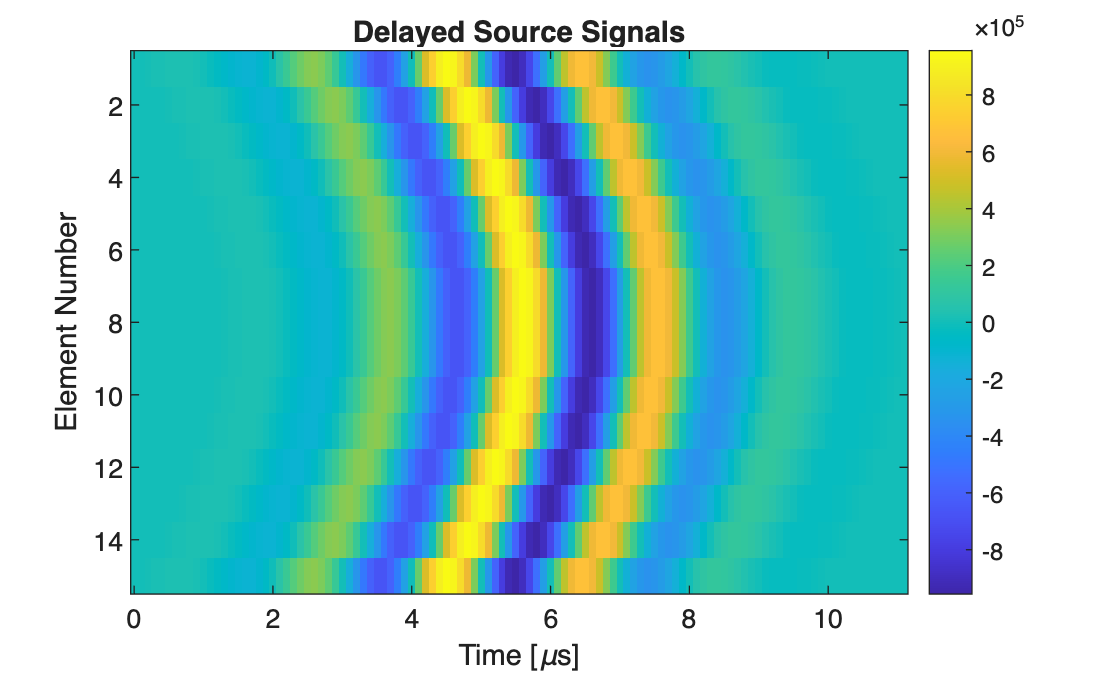

    ./ c0;

time_delays = ...
    time_delays ...
    - min(time_delays);

%% SHOW DELAYS

figure;

stem( ...
    1:element_num, ...
    time_delays * 1e6, ...
    'filled');

xlabel('Element Number');
ylabel('Delay [\mus]');

title('Transmit Focusing Delays');

grid on;

%% CREATE SOURCE SIGNALS

signal_offset = ...
    round(time_delays / kgrid.dt);

source_sig = ...
    source_amp .* ...
    toneBurst( ...
    1 / kgrid.dt, ...

    source_f0, ...
    source_cycles, ...
    'SignalOffset', ...
    signal_offset);


Computing distributed source signal...
  calculating binary mask...                  completed in 0.084282s
  approximate size of source matrix:          1.4 MB (double precision)
  calculating element 1 grid weights...       completed in 0.021556s
  calculating element 1 distributed source... completed in 0.005324s
  calculating element 2 grid weights...       completed in 0.010658s
  calculating element 2 distributed source... completed in 0.001627s
  calculating element 3 grid weights...       completed in 0.010839s
  calculating element 3 distributed source... completed in 0.000586s
  calculating element 4 grid weights...       completed in 0.012481s
  calculating element 4 distributed source... completed in 0.001112s
  calculating element 5 grid weights...       completed in 0.016874s
  calculating element 5 distributed source... completed in 0.000497s
  calculating element 6 grid weights...       completed in 0.007838s
  calculating element 6 distributed source... completed in 0.

%% SHOW SOURCE SIGNALS

figure;

imagesc( ...
    kgrid.t_array(1:size(source_sig,2)) * 1e6, ...
    1:element_num, ...
    source_sig);

xlabel('Time [\mus]');
ylabel('Element Number');

title('Delayed Source Signals');

colorbar;
axis tight;
%% DISTRIBUTE SIGNALS OVER kWaveArray
source.p = ...
    karray.getDistributedSourceSignal( ...
        kgrid, ...
        source_sig);

%% SENSOR
% Record maximum pressure over the whole grid
sensor.mask = ones( ...

Running k-Wave simulation...
  start time: 31-Aug-2026 16:13:52
  reference sound speed: 1500m/s
  dt: 100ns, t_end: 60us, time steps: 601
  input grid size: 128 by 128 by 128 grid points (64 by 64 by 64mm)
  maximum supported frequency: 1.5MHz
  expanding computational grid...
  computational grid size: 148 by 148 by 148 grid points
           Use dimension sizes with lower prime factors to improve speed
  casting variables to single type...
  precomputation completed in 0.65047s
  starting time loop...
  estimated simulation time 2min 22.7953s...
  simulation completed in 2min 18.2877s
  total computation time 2min 18.9829s


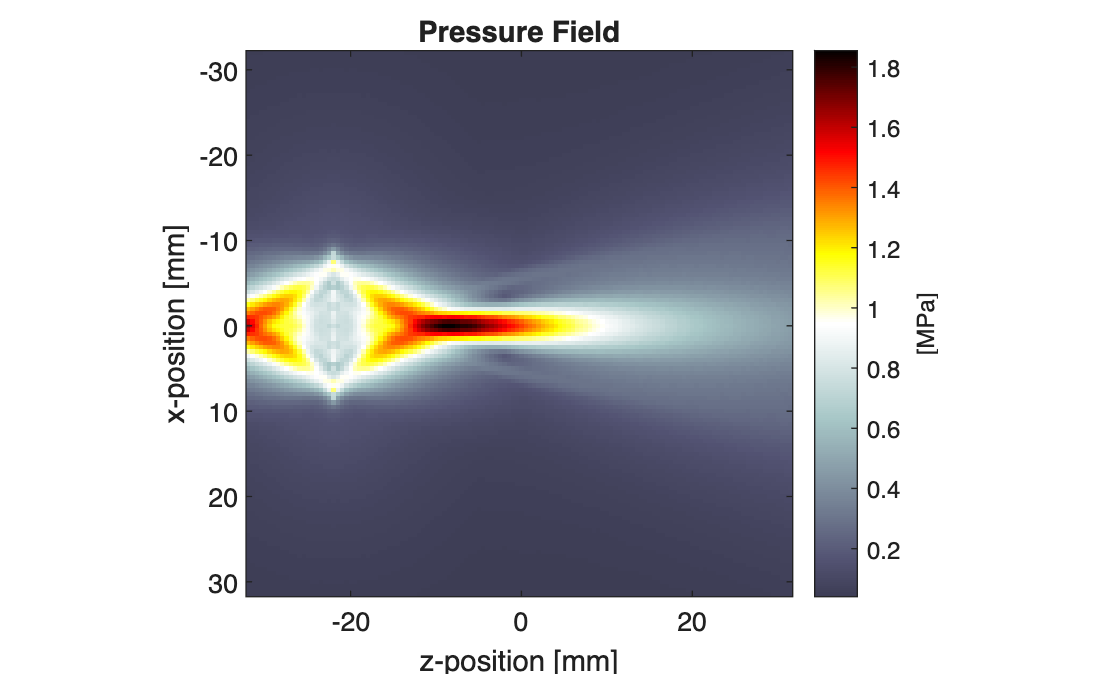

    Nx, ...
    Ny, ...
    Nz);

sensor.record = {'p_max'};

%% SIMULATION

input_args = { ...
    'PMLInside', false, ...
    'PMLSize', 10, ...
    'PlotPML', false, ...
    'DataCast', 'single'};

sensor_data = ...
    kspaceFirstOrder3D( ...
        kgrid, ...
        medium, ...
        source, ...
        sensor, ...
        input_args{:});
%% RECONSTRUCT MAXIMUM PRESSURE FIELD
p_max = reshape( ...
    sensor_data.p_max, ...
    Nx, ...
    Ny, ...
    Nz);

%% SELECT CENTRAL Y SLICE
y_slice = round(Ny / 2);

pressure_slice = ...
    squeeze( ...
        p_max(:, y_slice, :));

pressure_slice = ...
    pressure_slice / 1e6;


%% PLOT PRESSURE FIELD
figure;

imagesc( ...
    kgrid.z_vec * 1e3, ...
    kgrid.x_vec * 1e3, ...
    pressure_slice);

axis image;

xlabel('z-position [mm]');
ylabel('x-position [mm]');

title('Pressure Field');

colormap(getColorMap);
colorbar;

cb = colorbar;
ylabel(cb, '[MPa]');